alldata = datcomimport('astdatcom.out', true, 0);


data= alldata{1}

data = struct with fields:
        case: 'SKYHOGG BODY-WING-HORIZONTAL TAIL-VERTICAL TAIL CONFIG'
        mach: [0.1000 0.2000]
         alt: [5000 8000]
       alpha: [-2 0 2 4 8]
       nmach: 2
        nalt: 2
      nalpha: 5
       rnnub: []
      hypers: 0
        loop: 2
        sref: 225.8000
        cbar: 5.7500
       blref: 41.1500
         dim: 'ft'
       deriv: 'deg'
      stmach: 0.6000
      tsmach: 1.4000
        save: 0
       stype: []
        trim: 0
        damp: 1
       build: 1
        part: 0
     highsym: 0
     highasy: 0
     highcon: 0
        tjet: 0
      hypeff: 0
          lb: 0
         pwr: 0
        grnd: 0
       wsspn: 18.7000
       hsspn: 5.7000
      ndelta: 0
       delta: []
      deltal: []
      deltar: []
         ngh: 0
      grndht: []
      config: [1×1 struct]
     version: 1976
          cd: [5×2×2 double]
          cl: [5×2×2 double]
          cm: [5×2×2 double]
          cn: [5×2×2 double]
          ca: [5×2×2 double]
         xcp: [5

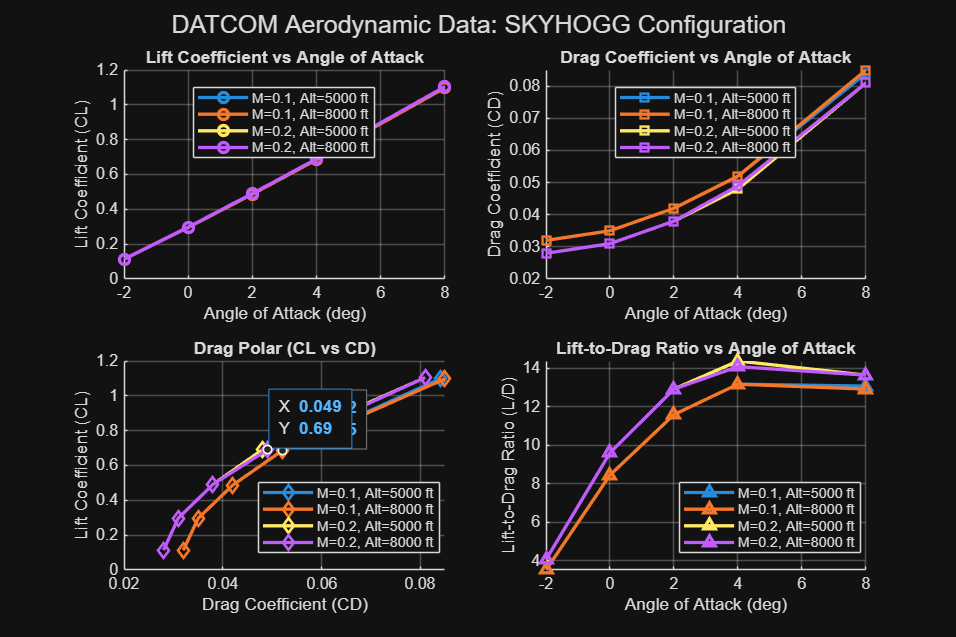

%plot the lift and drag plots
% Example data (replace these with your actual data)
% Extract data from the DATCOM structure
alpha = data.alpha;          % Angle of attack: [-2 0 2 4 8]
mach = data.mach;           % Mach numbers: [0.1000 0.2000]
alt = data.alt;             % Altitudes: [5000 8000]
CL = data.cl;               % Lift coefficient [5×2×2 double]
CD = data.cd;               % Drag coefficient [5×2×2 double]

% Create figure with subplots
figure('Position', [100, 100, 1200, 800]);

% Plot 1: Lift Coefficient vs Alpha
subplot(2, 2, 1);
hold on;
% Plot for different Mach numbers and altitudes
for i = 1:length(mach)
    for j = 1:length(alt)
        plot(alpha, CL(:, i, j), 'o-', 'LineWidth', 2, ...
             'DisplayName', sprintf('M=%.1f, Alt=%d ft', mach(i), alt(j)));
    end
end
xlabel('Angle of Attack (deg)');
ylabel('Lift Coefficient (CL)');
title('Lift Coefficient vs Angle of Attack');
legend('show', 'Location', 'best');
grid on;
hold off;

% Plot 2: Drag Coefficient vs Alpha
subplot(2, 2, 2);
hold on;
for i = 1:length(mach)
    for j = 1:length(alt)
        plot(alpha, CD(:, i, j), 's-', 'LineWidth', 2, ...
             'DisplayName', sprintf('M=%.1f, Alt=%d ft', mach(i), alt(j)));
    end
end
xlabel('Angle of Attack (deg)');
ylabel('Drag Coefficient (CD)');
title('Drag Coefficient vs Angle of Attack');
legend('show', 'Location', 'best');
grid on;
hold off;

% Plot 3: Drag Polar (CL vs CD)
subplot(2, 2, 3);
hold on;
for i = 1:length(mach)
    for j = 1:length(alt)
        plot(CD(:, i, j), CL(:, i, j), 'd-', 'LineWidth', 2, ...
             'DisplayName', sprintf('M=%.1f, Alt=%d ft', mach(i), alt(j)));
    end
end
xlabel('Drag Coefficient (CD)');
ylabel('Lift Coefficient (CL)');
title('Drag Polar (CL vs CD)');
legend('show', 'Location', 'best');
grid on;
hold off;

% Plot 4: L/D Ratio vs Alpha
subplot(2, 2, 4);
hold on;
for i = 1:length(mach)
    for j = 1:length(alt)
        LD_ratio = CL(:, i, j) ./ CD(:, i, j);
        plot(alpha, LD_ratio, '^-', 'LineWidth', 2, ...
             'DisplayName', sprintf('M=%.1f, Alt=%d ft', mach(i), alt(j)));
    end
end
xlabel('Angle of Attack (deg)');
ylabel('Lift-to-Drag Ratio (L/D)');
title('Lift-to-Drag Ratio vs Angle of Attack');
legend('show', 'Location', 'best');
grid on;
hold off;

% Add overall title
sgtitle('DATCOM Aerodynamic Data: SKYHOGG Configuration');

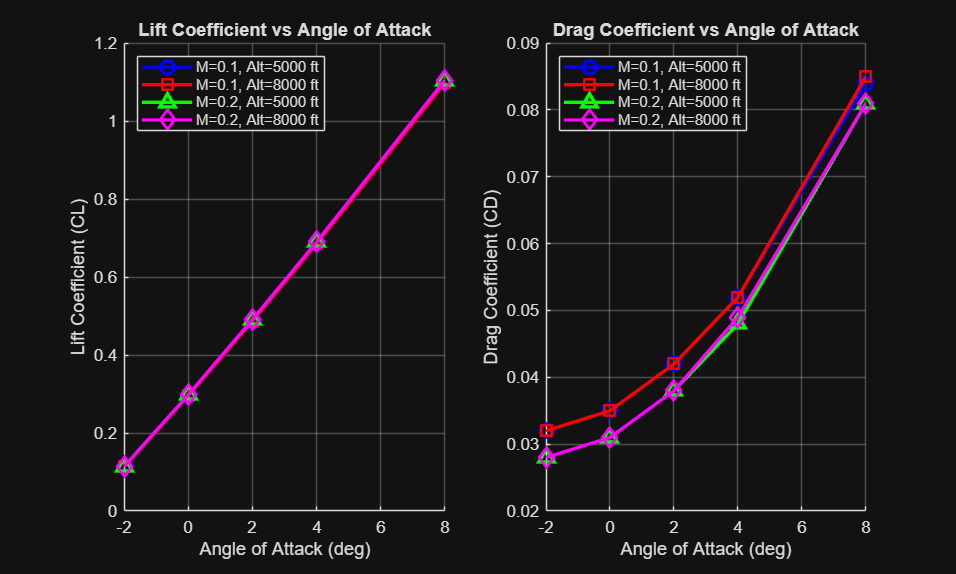


% Alternative: Single plot comparing conditions
figure('Position', [200, 200, 1000, 600]);

% Subplot 1: Lift curves
subplot(1, 2, 1);
hold on;
colors = ['b', 'r', 'g', 'm'];
markers = {'o', 's', '^', 'd'};
plot_idx = 1;
for i = 1:length(mach)
    for j = 1:length(alt)
        plot(alpha, CL(:, i, j), [colors(plot_idx) markers{plot_idx} '-'], ...
             'LineWidth', 2, 'MarkerSize', 8, ...
             'DisplayName', sprintf('M=%.1f, Alt=%d ft', mach(i), alt(j)));
        plot_idx = plot_idx + 1;
    end
end
xlabel('Angle of Attack (deg)');
ylabel('Lift Coefficient (CL)');
title('Lift Coefficient vs Angle of Attack');
legend('show', 'Location', 'northwest');
grid on;
hold off;

% Subplot 2: Drag curves
subplot(1, 2, 2);
hold on;
plot_idx = 1;
for i = 1:length(mach)
    for j = 1:length(alt)
        plot(alpha, CD(:, i, j), [colors(plot_idx) markers{plot_idx} '-'], ...
             'LineWidth', 2, 'MarkerSize', 8, ...
             'DisplayName', sprintf('M=%.1f, Alt=%d ft', mach(i), alt(j)));
        plot_idx = plot_idx + 1;
    end
end
xlabel('Angle of Attack (deg)');
ylabel('Drag Coefficient (CD)');
title('Drag Coefficient vs Angle of Attack');
legend('show', 'Location', 'northwest');
grid on;
hold off;


% Display some key information
fprintf('DATCOM Data Summary:\n');

DATCOM Data Summary:


fprintf('Configuration: %s\n', data.case);

Configuration: SKYHOGG BODY-WING-HORIZONTAL TAIL-VERTICAL TAIL CONFIG


fprintf('Mach numbers: [%.1f, %.1f]\n', mach(1), mach(2));

Mach numbers: [0.1, 0.2]


fprintf('Altitudes: [%d, %d] ft\n', alt(1), alt(2));

Altitudes: [5000, 8000] ft


fprintf('Alpha range: [%d, %d] deg\n', alpha(1), alpha(end));

Alpha range: [-2, 8] deg


fprintf('Reference area: %.1f ft²\n', data.sref);

Reference area: 225.8 ft²


fprintf('Reference chord: %.1f ft\n', data.cbar);

Reference chord: 5.8 ft


fprintf('Reference span: %.1f ft\n', data.blref);

Reference span: 41.1 ft
